clear;
syms x y; 
z = x*y + y^3 + sin(x) + 9

$$z = y^{3}+x\,y+\sin\left(x\right)+9$$


% -4<x<+4, -1<y<0.5

x_medio=(-4+4)/2;
y_medio=(-1+0.5)/2;
k1=subs(subs(diff(z,x), x, x_medio), y, y_medio);
k2=subs(subs(diff(z,y), x, x_medio), y, y_medio);
z_medio=subs(subs(z,x,x_medio),y,y_medio);

z_linealizada=z_medio+k1*(x-x_medio)+k2*(y-y_medio)

$$z\_linealizada = \frac{3\,x}{4}+\frac{3\,y}{16}+\frac{289}{32}$$


double(289/32)

ans = 9.0313

x1=linspace(-4,4);
y1=linspace(-1,0.5);
lin_ploteada=subs(z_linealizada,{x,y},{x1,y1});
ploteada=subs(z,{x,y},{x1,y1});

%a
e_i_z=double(subs(z,{x,y},{-4,-1}));
e_i_zl=double(subs(z_linealizada,{x,y},{-4,-1}));
e_d_z=double(subs(z,{x,y},{4,0.5}));
e_d_zl=double(subs(z_linealizada,{x,y},{4,0.5}));

e_absoluto_i=abs(e_i_z-e_i_zl);
e_absoluto_d=abs(e_d_z-e_d_zl);

e_relativo_i=e_absoluto_i/e_i_z;
e_relativo_d=e_absoluto_d/e_d_z;
e_relativo=(e_relativo_i+e_relativo_d)/2

e_relativo = 0.3557


diferencia=lin_ploteada-ploteada;
e_a=double(abs(diferencia));
e_a_mean=mean(e_a)

e_a_mean = 1.5136

e_r=e_a./ploteada;
e_r_mean=abs(double(mean(e_r)))

e_r_mean = 0.1414

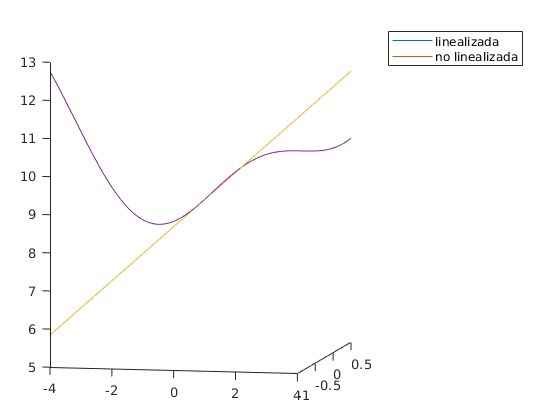




%b
plot3(x1, y1, lin_ploteada)
hold on
plot3(x1, y1, ploteada)
legend('linealizada', 'no linealizada')